# 二項分布

## 二項分布

平均値が$\eta$となるミクロな状態の出現確率をプロットする

$N$: コインの総数

$p$：表が出る確率

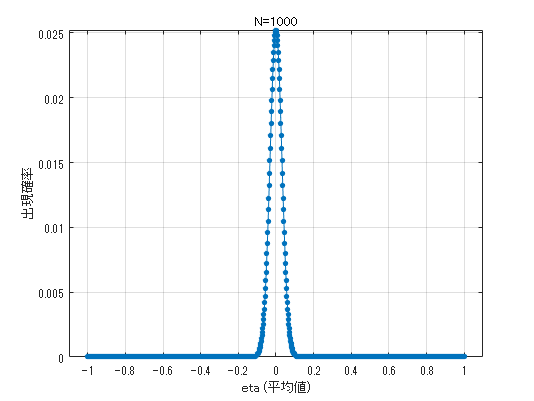

N = 1000;

p = 0.5;

x = 0:N;
y = binopdf(x, N, p);

figure;
plot(2*(x-N*p)/N, y,'.-','MarkerSize',12)

title(strcat('N= ',int2str(N)));
xlabel("eta (平均値)");
ylabel("出現確率");
xlim([-1.1 1.1])
ylim([0 Inf])
grid on

## 正規分布とのフィッティング

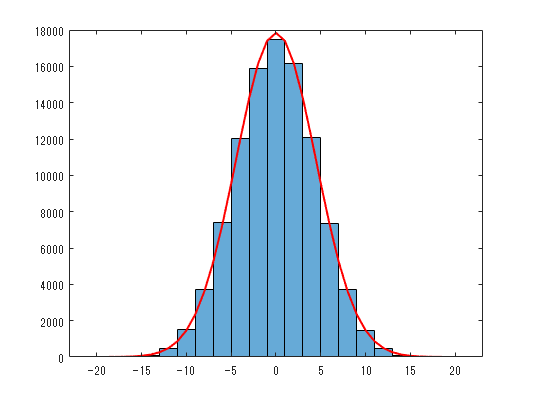

%random walk 
N = 100000; %試行回数
T = 20; %コイン数

r = sign(rand(N, T)-0.5); %各コインの固有状態
w = cumsum(r,2); %各試行における全コインの和

w(:, T);
 

nbins = [-T-1:2:T+1];
histogram(w(:, T), nbins)

hold on
x = -T-1:1:T+1;
y = (2*N)*1/sqrt(2*pi*T)*exp(-(x).^2/(2*T));
plot(x, y, 'r', 'LineWidth',1.5)
hold off

## Animation for time evolution of frequency distribution of massive coin toss into normal distribution

- Massive coin toss is equivalent to random walk.

- Frequency distribution of massive coin toss is subject to binomial distribution.

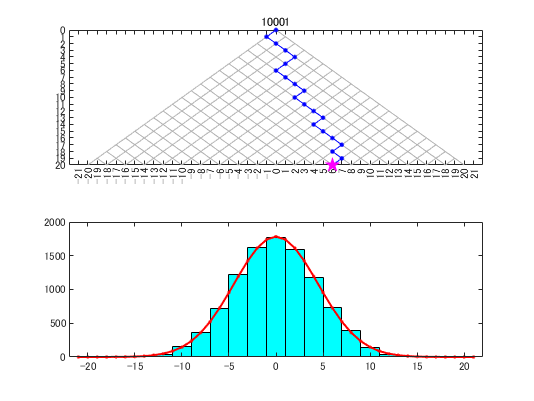

%random walk 
N = 10001; %試行回数
T = 20; %コイン数

r = sign(rand(N, T)-0.5); %各コインの固有状態
w = cumsum(r,2); %各試行における全コインの和r

Mtr = 1:1:T;

tiledlayout(2,1)            % Introduced in R2019b
nexttile                    % Introduced in R2019b

X0 = -T:T;
Y0 = -0*X0 + T+1;
plot(X0, Y0)
%grid on
xticks(-T-1:1:T+1)
yticks(0:1:T)
xlim([-T-2 T+2])
ylim([0 T])
ax = gca;
ax.YDir = 'reverse';
hold on
for j = 0:1:T-1
    plot(X0(T+1-j:2*T+1-2*j),  X0(T+1-j:2*T+1-2*j)+2*j, '-', "Color",[0.7 0.7 0.7], 'LineWidth', 0.1)
    plot(X0(2*j+1:T+1+j), -X0(2*j+1:T+1+j)+2*j, '-', "Color",[0.7 0.7 0.7], 'LineWidth', 0.1)
end
%plot(X0, -X0, '-', "Color",[0.3 0.3 0.3], 'LineWidth', 0.1)
%plot(X0,  X0, '-', "Color",[0.3 0.3 0.3], 'LineWidth', 0.1)
%pbaspect([2 1 1])


Xp = w(1,:);
Yp = Mtr;
hh0 = plot([0 Xp],[0 Yp], '.-b', "MarkerSize",10);
hh2 = plot([Xp(T)],[Yp(T)], 'pm', "MarkerSize",10, "MarkerFaceColor",'m');
ht = title("1");
pause(0.5);


%hh2 = plot((w(1,tr)+tr)/2,(-w(1,tr)+tr)/2, 'o');

hold off

nexttile
nbins = [-T-1:2:T+1];
[Nhh3, Ehh3] =  histcounts(w(1, T), nbins);
%hh3 = plot([-T:2:T], Nhh3);
hh3 = bar([-T:2:T], Nhh3, 1, "FaceColor",'c');
hold on
xlim([-T-2 T+2]);
x = -T-1:1:T+1;
y = (2*1)*1/sqrt(2*pi*T)*exp(-(x).^2/(2*T)); %normal distribution
hh4 = plot(x, y, '.-r', 'LineWidth',1.5);
%pbaspect([2 1 1])
hold off

NS = (N-1)/1000;
for j = 1:NS:N
    Xp = w(j,:);
    Yp = Mtr;
    %----------
    hh0.XData = [0 Xp];
    hh0.YData = [0 Yp];
    %----------
    hh2.XData = [Xp(T)];
    hh2.YData = [Yp(T)];
    %----------
    ht.String = j;
    %----------
    [Nhh3, Ehh3] =  histcounts(w(1:j, T), nbins);
    hh3.YData = Nhh3;
    %----------
    hh4.YData = (2*j)*1/sqrt(2*pi*T)*exp(-(x).^2/(2*T));
    %----------
    drawnow
end

## 参考文献

- [https://jp.mathworks.com/help/stats/binomial-distribution.html](https://jp.mathworks.com/help/stats/binomial-distribution.html)

- [https://blogs.mathworks.com/pick/2021/03/26/animation-playback-controls-in-live-scripts-r2021a/](https://blogs.mathworks.com/pick/2021/03/26/animation-playback-controls-in-live-scripts-r2021a/)